# === Frequency Analysis ===

close all; clear; clc

distanceConversion = 0.02;
forceConversion = 0.0000478305936073059;
experimentTime = 30; % seconds

## == Read Data from file ==

filename = "TPU-16.05.25/arduino_dataPERIODIC.csv";
rawData = readmatrix(filename);

## == Extract Data ==

distance = rawData(:, 1) * distanceConversion

distance =     0.0600
   -0.2000
   -0.4800
   -0.2000
    0.1000
    0.3800
    0.3400
    0.0600
   -0.2400
   -0.4600


force = rawData(:, 2) * forceConversion

force =     1.0069
   -0.0029
   -1.0319
   -1.4997
   -0.7787
    0.2803
    1.1037
    0.8559
   -0.1806
   -1.1875


## == Frequency Analysis Preperation ==

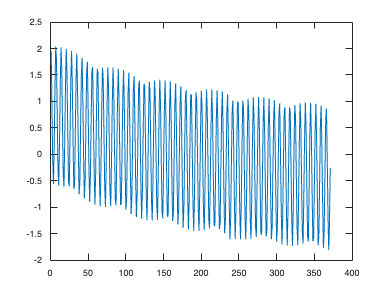

%% Define sampling rate

sampleSize = size(distance);
L = sampleSize(1);

fe = L / experimentTime; % sampling frequency

h = 1/fe; % sampling period

data = force - mean(force);
fdata = fft(data);

figure(1)
plot(data)

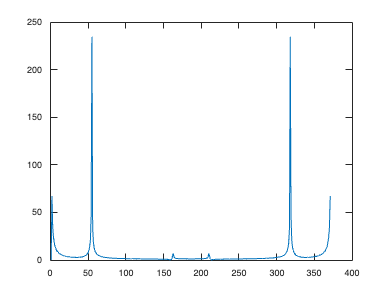


figure(2)
plot(abs(fdata))


% peak @ 55

fdata(54)

ans = -46.5406 - 2.8974i

fdata(55)

ans = 2.3460e+02 + 1.7040e+00i

fdata(56)

ans = 33.7549 - 0.2975i


% conjugate peak @ 318

fdata(319)

ans = -46.5406 + 2.8974i

fdata(318)

ans = 2.3460e+02 - 1.7040e+00i

fdata(317)

ans = 33.7549 + 0.2975i


middlePoint = L/2;
middlePointRound = round(middlePoint);

% 4th order low-pass filter with wn = 56 (cutoff frequency)

[B, A] = butter(4, 56/middlePoint)

B =     0.0189    0.0758    0.1137    0.0758    0.0189


A =     1.0000   -1.5554    1.2604   -0.4768    0.0749


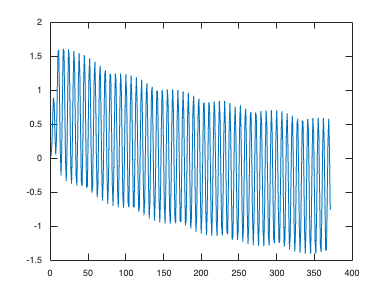


% filter signal

filteredSignal = filter(B, A, data);

figure(3)
plot(filteredSignal);

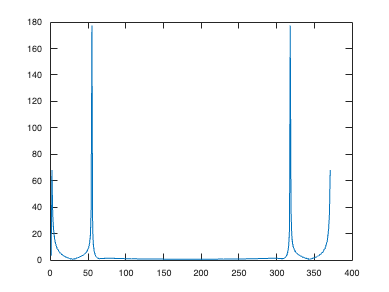


fFilteredSignal = fft(filteredSignal);

figure(4)
plot(abs(fFilteredSignal))


% high-pass filter -> @ 45 
[Bh, Ah] = butter(4, 45/middlePoint, 'high');
sum(Bh) % must be zero for high-pass

ans = 0

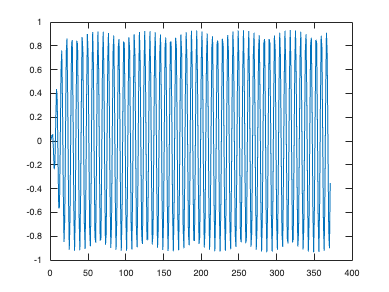


doubleFilteredSignal = filter(Bh, Ah, filteredSignal);

fDoubleFilteredSignal = fft(doubleFilteredSignal);

figure(5)
plot(doubleFilteredSignal)

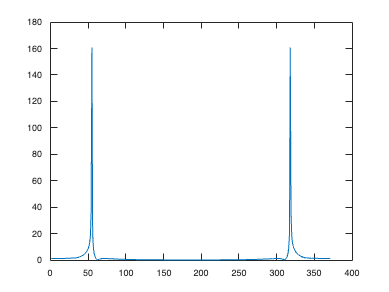


figure(6)
plot(abs(fDoubleFilteredSignal))


% windowedSignal = data .* (hann(L)');
% 
% figure(6)
% plot(windowedSignal)
% 
% figure(7) 
% plot(abs(fft(windowedSignal)))